Визуализирует следующую функцию 

2) Нахождение максимальной частоты сигнала. Т.к. нам даны изначальный гармоники - достаточно найти максимальную частоту одной из них: 

Гармонический сигнал описывается следующим образом: 

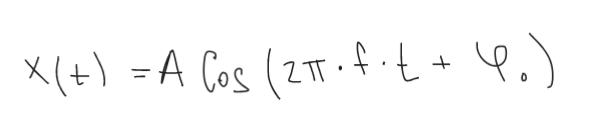

cos(2*pi*f) - частота f (она максимальная)

т.к. наша частота f=18 => (по т, Котельникова: частота дискретизации должна быть минимум в 2 раза больше для того, чтобы мы смогли преобразовать сигнал и восстановить) => мминимальная частота дискретизации = 36 отсчётов в секунду

function analyze_signal()
    f = 18; 
    y = @(t) 8 * sin (2 * pi * f * t + pi/3); 

    function draw_signal(y) 
        fs = 1000;
        t = 0:1/fs:1; 
        
        figure; 
            title("График сигнала");
            plot(t, y(t));

            xlabel('time (s)');
            ylabel('Amplitude');
            grid on; 
    end 

    %draw_signal(y); 

    % Задаём частоту дискретизации и разбиваем ось времени
    fs = f * 2; 
    t = 0:1/fs:1;

    % Сохраняем значение функций в массив
    samples = arrayfun(y, t);

    function draw_samples(samples, t)
        figure; 
            title("Дискретизированный сигнал");
            plot(t, samples);
            xlabel('time (s)');
            ylabel('Amplitude');
            grid on; 
    end 

    %draw_samples(samples, t); 

    reference_ppf = fft(samples); 

    ppf = zeros(1, length(t)); 
    for i=1:length(t)
        ppf(i) = discrete_furie_tr(length(t), samples, i);
    end 

    reference_opf = ifft(reference_ppf); 
    
    opf = zeros(1, length(t)); 
    for i=1:length(t)
        opf(i) = discrete_reverse_furie_tr(length(t), ppf, i);
    end 

    function draw_fourier(reference_opf, opf, t) 
        figure; 
            subplot(2,1,1); 
            plot(t, reference_opf); 
            xlabel('time (s)');
            ylabel('Amplitude');
            title("График восстановления ifft/fft")

            subplot(2,1,2); 
            plot(t, opf); 
            xlabel('time (s)');
            ylabel('Amplitude');
            title("Собственная реализация ifft/fft")
    end 

    function draw_diff_opf_signal(samples, opf, t) 
        figure; 
            subplot(2,1,1); 
            plot(t, samples); 
            xlabel('time (s)');
            ylabel('Amplitude');
            title("Разница между обратно преобразованным цифровым сигналом и сигналом")

            subplot(2,1,2); 
            plot(t, opf); 
            xlabel('time (s)');
            ylabel('Amplitude');
            title("Разница между обратно преобразованным цифровым сигналом и сигналом")
    end 

    %draw_fourier(reference_opf, opf, t); 

    %draw_diff_opf_signal(samples, opf, t);

    fprintf("Ширина спектра: %.2f\n", max(ppf(:)));
    fprintf('Занято памяти (Кб): %.2f\n', whos("ppf").bytes / 1024);


    % задание 7
    fs_4x = fs * 4; 
    t_4x = 0:1/fs_4x:1;
    
    samples_4x = arrayfun(y, t_4x); 

    ppf_4x = fft(samples_4x); 
    opf_4x = ifft(ppf_4x); 

    function draw_diff_4x(t, t_4x, samples, samples_4x, ppf, ppf_4x, opf, opf_4x)
        figure; 
            title("Дискретизированный сигнал");
            plot(t, samples, 'DisplayName', 'Сигнал с частотой fs');
            hold on; 
                plot(t_4x, samples_4x, 'DisplayName', 'Сигнал с частотой 4fs');
            hold off; 
            xlabel('time (s)');
            ylabel('Amplitude');
            grid on; 
            legend('show');
    end 

    function draw_diff_opf_signal_4x(samples, opf, t) 
        figure; 
            subplot(2,1,1); 
            plot(t, samples); 
            xlabel('time (s)');
            ylabel('Amplitude');
            title("Разница между обратно преобразованным цифровым сигналом и сигналом")

            subplot(2,1,2); 
            plot(t, opf); 
            xlabel('time (s)');
            ylabel('Amplitude');
            title("Разница между обратно преобразованным цифровым сигналом и сигналом")
    end 

    %draw_diff_4x(t, t_4x, samples, samples_4x, ppf, ppf_4x, opf, opf_4x);
    %draw_diff_opf_signal_4x(samples_4x, opf_4x, t_4x); 

    fprintf("Ширина спектра: %.2f\n", max(ppf_4x(:)));
    fprintf('Занято памяти (Кб): %.2f\n', whos("ppf_4x").bytes / 1024);

    function quantization_test(y)
        fs = 8000;
        t = 0:1/fs:1; 

        original_signal = y(t); 
    
        bit_depths = [3, 4, 5, 6];
    
        for bits = bit_depths
            quantized_signal = quantize(original_signal, bits);
            
            Y = fft(original_signal);
            Y_quantized = fft(quantized_signal);
            
            amplitude_spectrum = abs(Y);
            amplitude_spectrum_quantized = abs(Y_quantized);
            
            quantization_error = original_signal - quantized_signal;
            mean_quantization_error = mean(abs(quantization_error));
            
            f = (0:length(original_signal)-1) * (fs / length(original_signal));
            
            figure;
            plot(f, amplitude_spectrum, 'b', 'DisplayName', 'Оригинальный сигнал');
            hold on;
            plot(f, amplitude_spectrum_quantized, 'r', 'DisplayName', sprintf('Квантованный сигнал (биты = %d)', bits));
            hold off;
            title(sprintf('Сравнение амплитудных спектров для %d бит', bits));
            xlabel('Частота (Гц)');
            ylabel('Амплитуда');
            xlim([0 fs/2]);
            legend show;
            grid on;
            
            fprintf('Средняя ошибка квантования для %d бит: %.4f\n', bits, mean_quantization_error);
        end
    end

    quantization_test(y);
end
